%Q1 e simulation
k_s=10.991;

k0 = 0.1*k_s;

list = [k0];

i=200;
for c=1:i-1
    kt= list(end, end);
    list=[list; update(kt,k_s)];
end

dynare model1f.mod;

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 2 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 10.9801,	 time = 0.116
Iter: 2,	 err. = 0.588256,	 time = 0.034
Iter: 3,	 err. = 0.463321,	 time = 0.033
Iter: 4,	 err. = 0.102543,	 time = 0.03
Iter: 5,	 err. = 0.00242509,	 time = 0.038
Iter: 6,	 err. = 1.08171e-06,	 time = 0.043

Total time of simulation: 0.397.
--------------------------------------------------------

Perfect foresight solution found.

Total computing time : 0h00m01s



kt_dyn = k(1:i);

dynare model1g.mod;

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 2 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


--------------------------------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 Initial err. = 10.4125,	 err. = 1.2212e-15,	 time = 0.018
--------------------------------------------------------------------------------

Perfect foresight solution found.

Total computing time : 0h00m00s


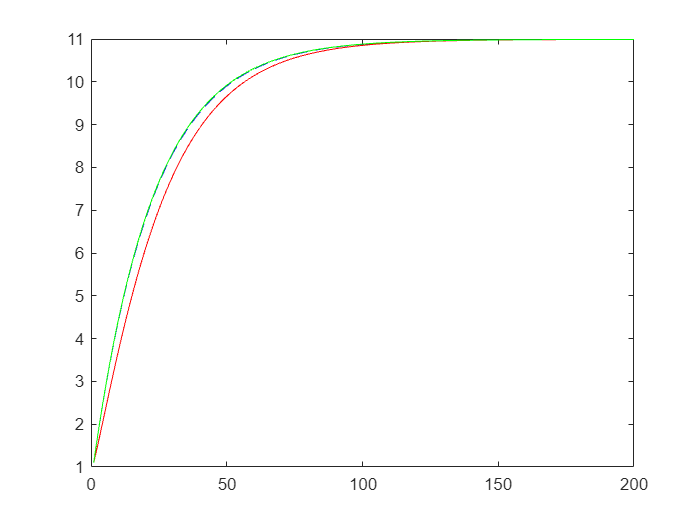


kt_la = k(1:i);
g1 = plot([1:i],list,'--b', [1:i], kt_dyn, 'r', [1:i], kt_la,'g');

%Q2
dynare model2c.mod;

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 3 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 3.66005,	 time = 0.12
Iter: 2,	 err. = 23.3743,	 time = 0.076


Iter: 3,	 err. = 23.3743,	 time = 0.037


Iter: 4,	 err. = 23.3743,	 time = 0.036


Iter: 5,	 err. = 23.3743,	 time = 0.036


Iter: 6,	 err. = 23.3743,	 time = 0.038


Iter: 7,	 err. = 23.3743,	 time = 0.031


Iter: 8,	 err. = 23.3743,	 time = 0.047


Iter: 9,	 err. = 23.3743,	 time = 0.042


Iter: 10,	 err. = 23.3743,	 time = 0.029


Iter: 11,	 err. = 23.3743,	 time = 0.029


Iter: 12,	 err. = 23.3743,	 time = 0.029


Iter: 13,	 err. = 23.3743,	 time = 0.035


Iter: 14,	 err. = 23.3743,	 time = 0.035


Iter: 15,	 err. = 23.3743,	 time = 0.052


Iter: 16,	 err. = 23.3743,	 time = 0.038


Iter: 17,	 err. = 23.3743,	 time = 0.034


Iter: 18,	 err. = 23.3743,	 time = 0.028


Iter: 19,	 err. = 23.3743,	 time = 0.044


Iter: 20,	 err. = 23.3743,	 time = 0.034


Iter: 21,	 err. = 23.3743,	 time = 0.031


Iter: 22,	 err. = 23.3743,	 time = 0.027


Iter: 23,	 err. = 23.3743,	 time = 0.027


Iter: 24,	 err. = 23.3743,	 time = 0.033


Iter: 25,	 err. = 23.3743,	 time = 0.027


Iter: 26,	 err. = 23.3743,	 time = 0.032


Iter: 27,	 err. = 23.3743,	 time = 0.028


Iter: 28,	 err. = 23.3743,	 time = 0.033


Iter: 29,	 err. = 23.3743,	 time = 0.041


Iter: 30,	 err. = 23.3743,	 time = 0.033


Iter: 31,	 err. = 23.3743,	 time = 0.035


Iter: 32,	 err. = 23.3743,	 time = 0.027


Iter: 33,	 err. = 23.3743,	 time = 0.026


Iter: 34,	 err. = 23.3743,	 time = 0.025


Iter: 35,	 err. = 23.3743,	 time = 0.026


Iter: 36,	 err. = 23.3743,	 time = 0.031


Iter: 37,	 err. = 23.3743,	 time = 0.028


Iter: 38,	 err. = 23.3743,	 time = 0.026


Iter: 39,	 err. = 23.3743,	 time = 0.028


Iter: 40,	 err. = 23.3743,	 time = 0.028


Iter: 41,	 err. = 23.3743,	 time = 0.026


Iter: 42,	 err. = 23.3743,	 time = 0.026


Iter: 43,	 err. = 23.3743,	 time = 0.029


Iter: 44,	 err. = 23.3743,	 time = 0.026


Iter: 45,	 err. = 23.3743,	 time = 0.026


Iter: 46,	 err. = 23.3743,	 time = 0.026


Iter: 47,	 err. = 23.3743,	 time = 0.027


Iter: 48,	 err. = 23.3743,	 time = 0.041


Iter: 49,	 err. = 23.3743,	 time = 0.044


Iter: 50,	 err. = 23.3743,	 time = 0.045


Total time of simulation: 2.983.
Maximum number of iterations is reached (modify option maxit).
--------------------------------------------------------------


Simulation of the perfect foresight model failed!
Switching to a homotopy method...
Iter. 	 | Lambda 	 | status 	 | Max. residual
++++++++++++++++++++++++++++++++++++++++++++++++++++++++
1 	 | 0.50000 	 | succeeded 	 | 3.688760e-08
2 	 | 1.00000 	 | succeeded 	 | 5.847909e-07
++++++++++++++++++++++++++++++++++++++++++++++++++++++++

Perfect foresight solution found.

Total computing time : 0h00m04s
Note: warning(s) encountered in MATLAB/Octave code



kt_dyn = k(1:i);

dynare model2d.mod;

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 3 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


--------------------------------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 Initial err. = 3.4708,	 err. = 1.9429e-16,	 time = 0.034
--------------------------------------------------------------------------------

Perfect foresight solution found.

Total computing time : 0h00m00s


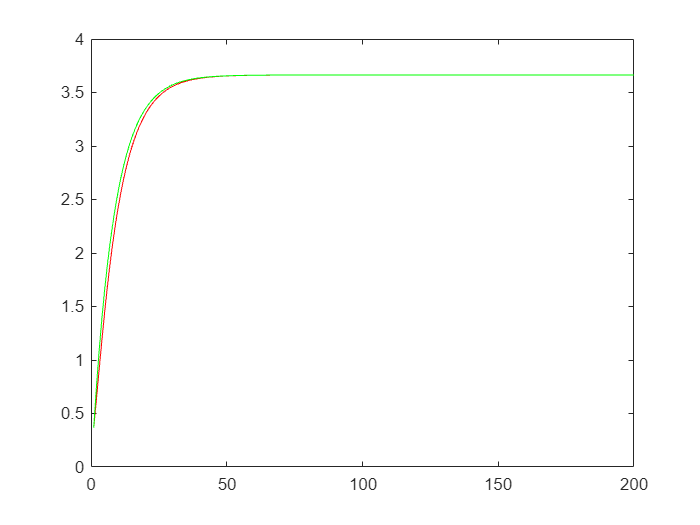


kt_la = k(1:i);

plot([1:i], kt_dyn, 'r', [1:i], kt_la,'g');

function kt1 = update(kt, k)
    %ct1 = 1.979*(kt-k) + c
    kt1 = 0.956*(kt-k) + k;
end